Looking through simulated gamma ray detector data and looking for patterns and outliers:

%h5disp("gammaray_lab4.h5")
mydata = h5read("gammaray_lab4.h5",'/data');
%columns: gps time (secs), solar phase (deg), earth longitude (deg),
%particle counts
time = mydata(:,1);
solarPhase = mydata(:,2);
longitude = mydata(:,3);
counts = mydata(:,4);

Plotting the Solar Phase and and Longitude of the sattelite over time.

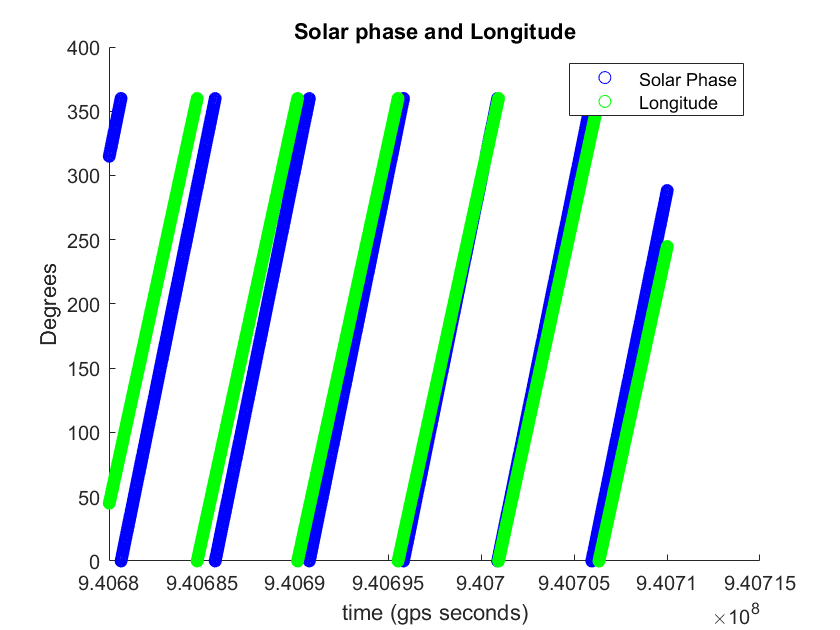

%Plotting solar phase and longtitude
hold on
scatter(mydata(1:300000,1),mydata(1:300000,2), "blue")
scatter(mydata(1:300000,1),mydata(1:300000,3), "green")
xlabel("time (gps seconds)")
ylabel("Degrees")
legend("Solar Phase", "Longitude")
title("Solar phase and Longitude")

Now I will find the period of the longitude vs time relationship

shortLongs = longitude(1:300000);

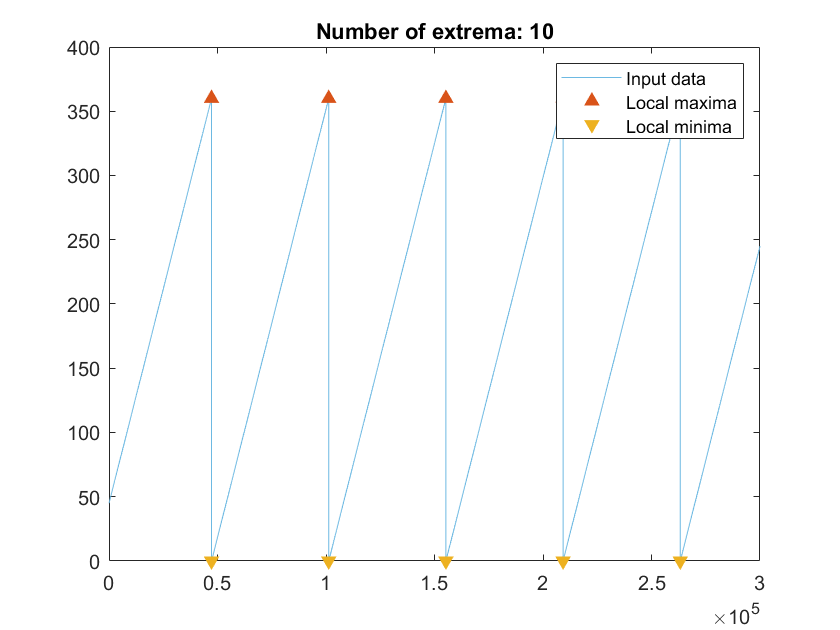

% Find local maxima and minima
maxIndices = islocalmax(shortLongs);
minIndices = islocalmin(shortLongs);

% Display results
clf
plot(shortLongs,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot local maxima
plot(find(maxIndices),shortLongs(maxIndices),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')

% Plot local minima
plot(find(minIndices),shortLongs(minIndices),'v','Color',[237 177 32]/255,...
    'MarkerFaceColor',[237 177 32]/255,'DisplayName','Local minima')
title(['Number of extrema: ' num2str(nnz(maxIndices)+nnz(minIndices))])
hold off
legend

x = find(maxIndices);
longitudePeriod = (x(2) - x(1)) * 100 %Taking the first interval and multiplying to find the period in milliseconds

longitudePeriod = 5400000

Notice the two have similar periods, but they are slightly differnt.

Next I will plot a the number of counts detected with respect to time for a short time period, as well as a histogram of all the counts in 100 ms incriments.

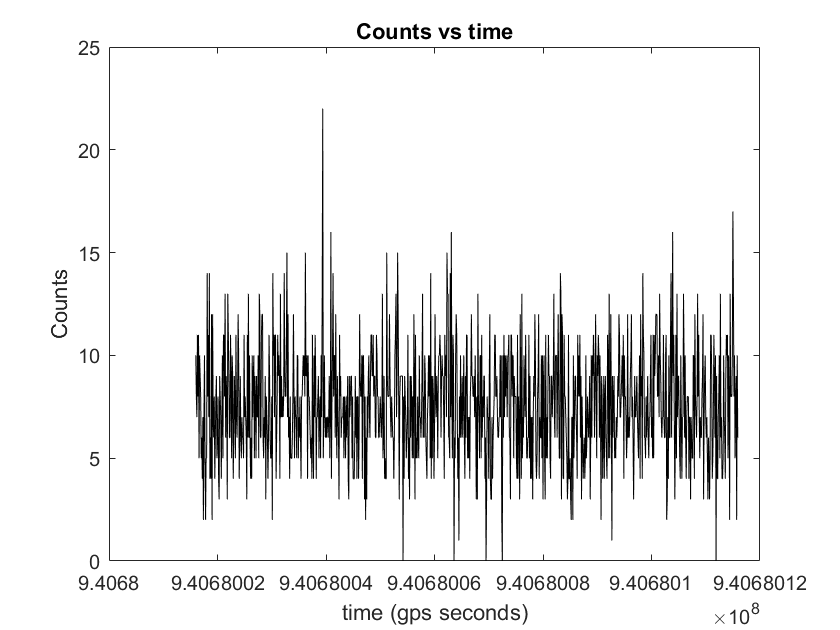

%plotting counts
figure
plot(mydata(1:1000,1),mydata(1:1000,4), "black")
xlabel("time (gps seconds)")
ylabel("Counts")
title("Counts vs time")

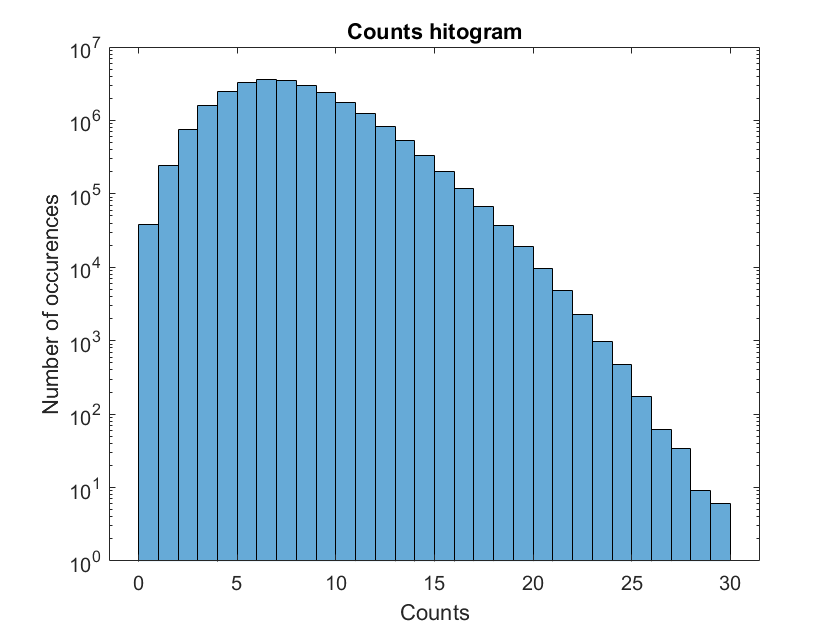


maxCounts = max(counts); 
histogram(counts, maxCounts)
xlabel("Counts")
ylabel("Number of occurences")
title("Counts hitogram")
set(gca,'YScale','log')

It is difficult to see if there is any pattern at all in the raw counts vs time plot. The histogram however shows a poission distribution, which is to be expected for a discrete observation with an expected value close to 0. There also do not appear to be any outliers from looking at the histogram plot, so we can reasonably assume that there is no signal contamination in this data, since it so closely matches what we would expect to see in a background distribution.

2) Looking for time dependence in the background, first by plotting weighted histograms of the counts for both the solar phase and longitude.

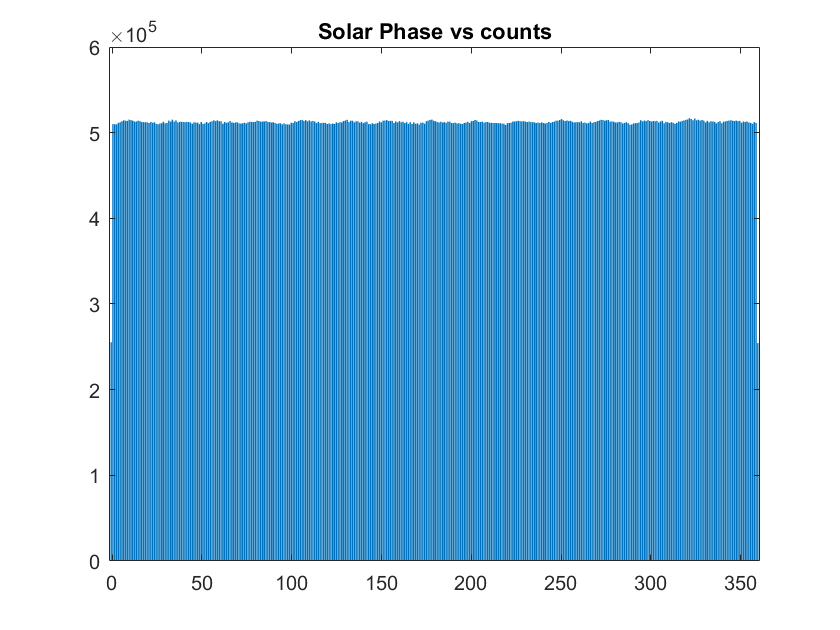

%Exploring
nbins = 360;
[solarCounts, intervals] = histwc(solarPhase, counts, nbins);
bar(intervals, solarCounts)
title("Solar Phase vs counts")

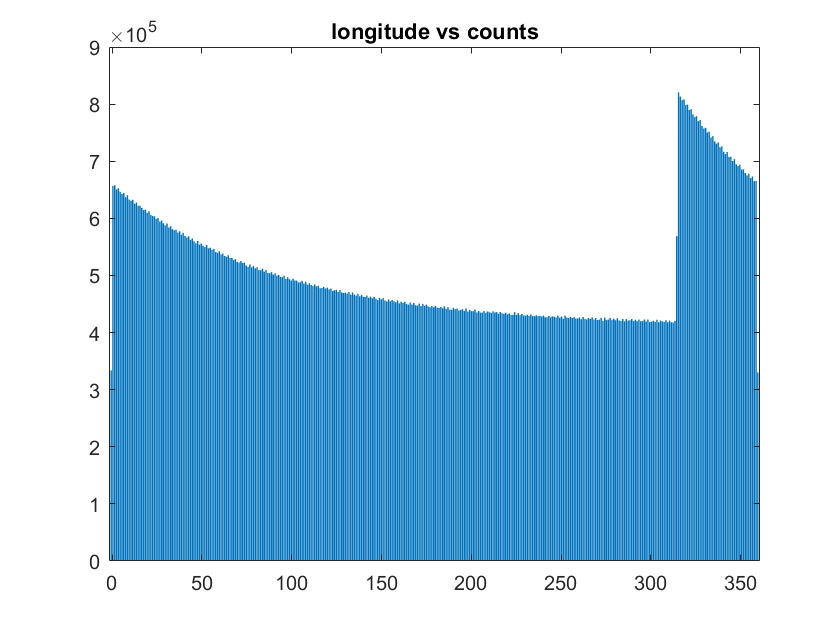


[longCounts, intervals] = histwc(longitude, counts, nbins);
bar(intervals, longCounts)
title("longitude vs counts")

There appears to be no correlation between the solar phase and the counts, while there is a relationship between the longitude and the counts, with a discontinuity at about 315 degrees longitude. Now to look at this in a 2-D histogram to more clearly see how the background distribution changes with logitude, as well as calculating the mean counts at each logitude.

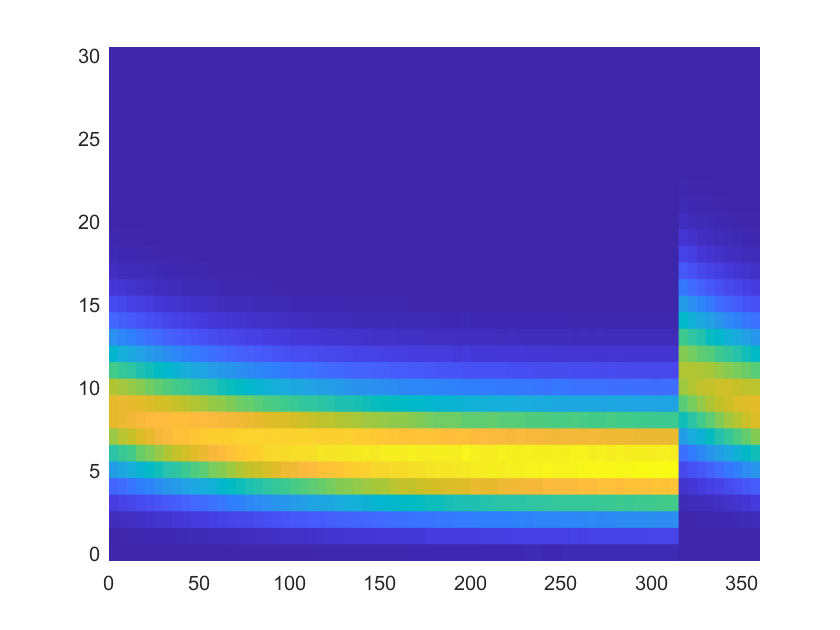

histogram2(longitude,counts,'DisplayStyle','tile','ShowEmptyBins','on');

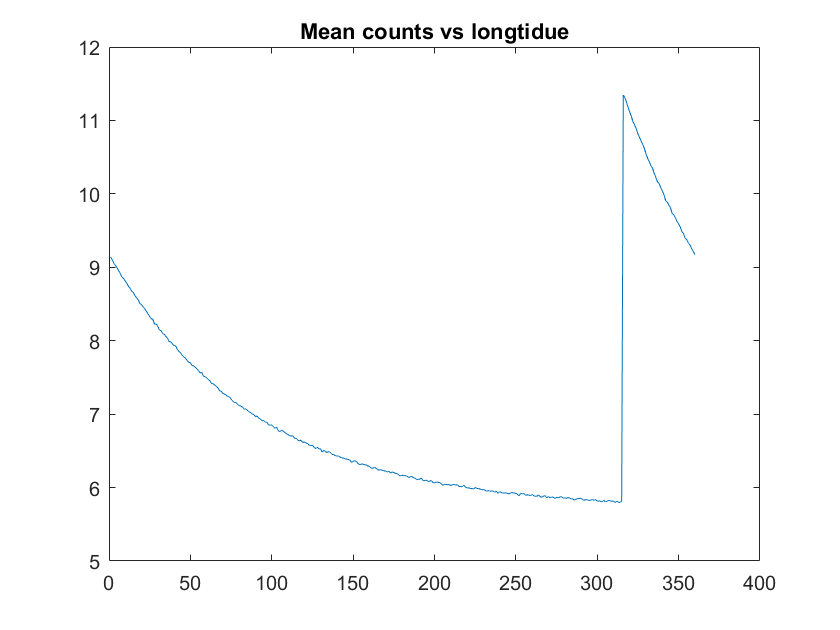


longSorted = sortrows(mydata, 3);
longs = longSorted(:,3);
countsSorted = longSorted(:,4);
longMeans = zeros(1,360);
firstIndicies = zeros(1,360);

for i = 0:359
    firstIndicies(i+1) = find(i == longs, 1);
end

for i = 1:359
    longMeans(i) = mean(countsSorted(firstIndicies(i):firstIndicies(i+1)));
end

longMeans(360) = mean(countsSorted(firstIndicies(360):length(countsSorted)));
degs = 1:360;

plot(degs, longMeans);
title("Mean counts vs longtidue")

The 2-D histogram shows that there appears to be a poission distribution for each logitude, and the peak of these distributions changes with the logitude. In the mean counts vs logitude plot, it appears that there is an exponential decay in the mean beginning at a peak of about 11.35 counts at 316 degrees, and falling to a minimum of about 5.79 counts right before 314 degrees. Because a poission distribution only needs one parameter to characterise it - $\lambda$, which is both the mean and the variance, finding the mean will give us this parameter to fully characterize the background distribution for any longitude.

Now I will shift the longitude by 315 degrees to curve fit an exponential to model the mean. Combining this model with the previous model for lognitude as a function of time will give a function for the $\lambda$ parameter for the poission distribution that describes the background distribution as a function of time.

y = [longMeans(316:360), longMeans(1:315)];
func = @(x1,degs)x1(3)*exp(x1(1)*degs) + x1(2);
x0 = [-0.01, 5, 11];
f = lsqcurvefit(func,x0,degs,y);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


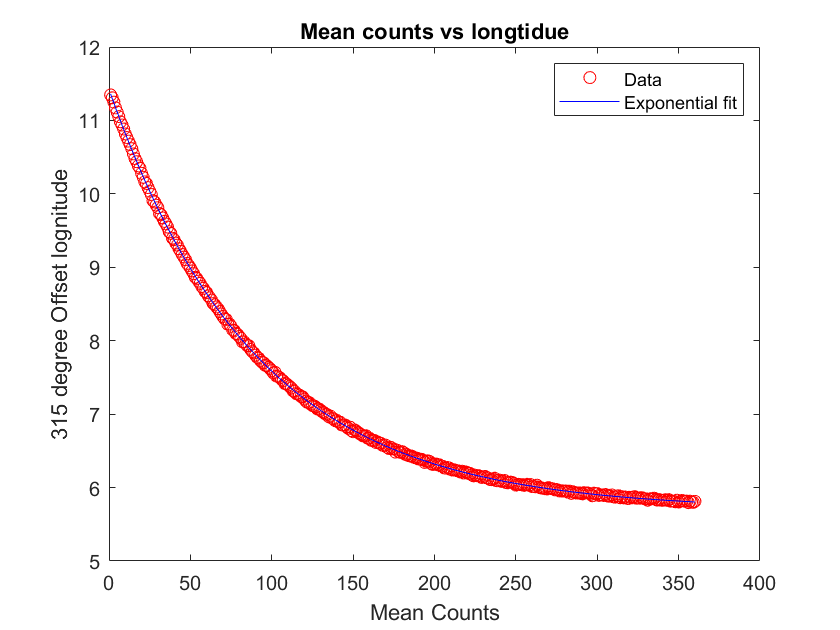

plot(degs, y, 'ro', degs, func(f, degs), 'b-');
xlabel("Mean Counts")
ylabel("315 degree Offset lognitude")
legend('Data','Exponential fit')
title("Mean counts vs longtidue")

fprintf("fit line = %f * e^(%f * (longitude - 315)) + %f", f(3), f(1), f(2))

fit line = 5.726119 * e^(-0.011099 * (longitude - 315)) + 5.698306


%Finding longitude vs time
%already found longitude period
%Finding the time where the mean counts hits its first max (316 degrees)
firstMaxIndex = find(longitude == 0.0, 1);
firstMaxTime = time(firstMaxIndex); 
fprintf("Longitude L(t) =  (time - (%i MODULO %i))MODULO  %i", firstMaxTime, longitudePeriod, longitudePeriod)

Longitude L(t) =  (time - (940684741 MODULO 5400000))MODULO  5400000

This fit can be used to find the lambda value for any logitude, then the longitude vs time function can turn it into a function of time.